% ========================================================================
% 飞镖气动恢复/阻尼 A 矩阵参数标定入口（CSV 版）
% ========================================================================
% 用途：
%   从 LQR 自稳飞行日志 CSV 中辨识：
%       Dp_ref_ac
%       Cm_pitch_ref_ac
%       Dq_ref_ac
%       Cm_yaw_ref_ac
%       Dr_ref_ac
%
% 使用方法：
%   1. 把飞行日志 CSV 放到本文件同目录，或填写完整路径。
%   2. 确认 CSV 列名和单位。
%   3. 运行本脚本。
%   4. 将生成的 dart_aero_A_identified_params.m 中参数复制到
%      dart_attitude_LQR_v1.m，或按需在主脚本中 run 该参数文件。
%
% CSV 至少需要这些列，单位必须如下：
%   t                         s
%   d_phi, d_theta, d_psi      rad
%   p, q, r                    rad/s
%   delta1..delta4             rad
%   V                          m/s，空速标量或近似速度标量
%
% 支持的常见别名见本文件底部 get_log_column 调用。
% ========================================================================

clear
close all
clc

## Step 1: 标定配置

% CSV 文件路径。默认假设 CSV 与本脚本同目录。
csv_file_ac = 'C:\Users\ynz\Desktop\制导\制导飞行日志\aero_cal_new.csv';

% 参考速度。辨识出的恢复/阻尼参数都定义在该速度处。
V_ref_ac = 4.0;              % m/s

% 角速度求导前的平滑窗口。日志噪声大就适当增大，比如 0.03~0.08 s。
smooth_window_s = 0.03;      % s

% 是否画拟合对比图。
do_plot = true;

% 是否保存结果 MAT 文件。
save_result_mat = true;

% 是否生成可复制的参数脚本。
write_param_file = true;

result_mat_file = "dart_aero_A_fit_result.mat";
param_file = "dart_aero_A_identified_params.m";

## Step 2: 检查 CSV 并辨识


--- Dart aero A identification result ---
V_ref_ac = 4;  % m/s
Dp_ref_ac = -51.129330639306865;  % roll damping, 1/s
Cm_pitch_ref_ac = 3.1517688545260216;  % pitch restoring, 1/s^2
Dq_ref_ac = 11.764010666008659;  % pitch damping, 1/s
Cm_yaw_ref_ac = 3.221851084768645;  % yaw restoring, 1/s^2
Dr_ref_ac = 11.320992247349444;  % yaw damping, 1/s
RMSE [p q r] = [304.134 38.629 14.986] rad/s^2
R^2  [p q r] = [0.4930 0.7556 0.7917]


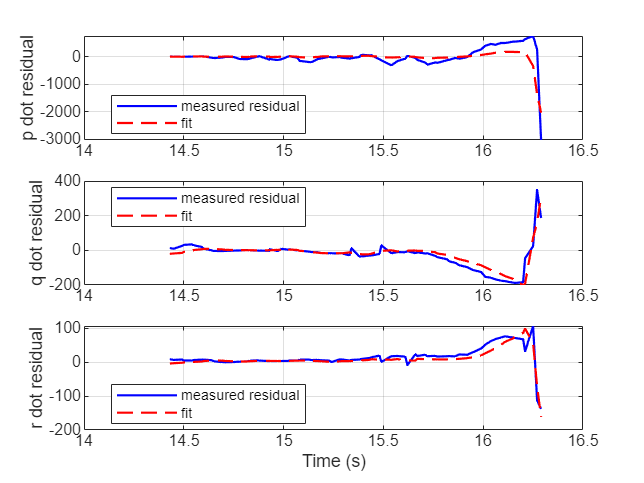

if ~isfile(csv_file_ac)
    error(["找不到 CSV 文件：%s\n" ...
        "请把飞行日志命名为 flight_log.csv 放到当前目录，" ...
        "或修改 csv_file_ac 为完整路径。"], csv_file_ac);
end

fit = fit_aero_A_params_from_csv(csv_file_ac, V_ref_ac, smooth_window_s, do_plot);

## Step 3: 保存结果

if save_result_mat
    save(result_mat_file, "fit");
    fprintf("已保存标定结果 MAT：%s\n", result_mat_file);
end

已保存标定结果 MAT：dart_aero_A_fit_result.mat



if write_param_file
    write_aero_param_file(param_file, fit);
    fprintf("已生成参数文件：%s\n", param_file);
end

已生成参数文件：dart_aero_A_identified_params.m



fprintf("\n复制到 dart_attitude_LQR_v1.m 的参数如下：\n");


复制到 dart_attitude_LQR_v1.m 的参数如下：


fprintf("DART_LQR_ENABLE_AERO_A = true;\n");

DART_LQR_ENABLE_AERO_A = true;


fprintf("V_ref_ac = %.17g;\n", fit.V_ref_ac);

V_ref_ac = 4;


fprintf("Dp_ref_ac = %.17g;\n", fit.Dp_ref_ac);

Dp_ref_ac = -51.129330639306865;


fprintf("Cm_pitch_ref_ac = %.17g;\n", fit.Cm_pitch_ref_ac);

Cm_pitch_ref_ac = 3.1517688545260216;


fprintf("Dq_ref_ac = %.17g;\n", fit.Dq_ref_ac);

Dq_ref_ac = 11.764010666008659;


fprintf("Cm_yaw_ref_ac = %.17g;\n", fit.Cm_yaw_ref_ac);

Cm_yaw_ref_ac = 3.221851084768645;


fprintf("Dr_ref_ac = %.17g;\n", fit.Dr_ref_ac);

Dr_ref_ac = 11.320992247349444;



function fit = fit_aero_A_params_from_csv(log_input, V_ref_ac, smooth_window_s, do_plot)
rho_ac = 1.225;
Ixx_ac = 413276.151e-9;
Iyy_ac = 5056825.175e-9;
Izz_ac = 5062679.784e-9;
r_ac = 0.150;
a_ac = 0.120;
S_ac = 0.0050;
CLalpha_ac = 5.0;

log_tbl = load_log_table(log_input);

t       = get_log_column(log_tbl, ["t", "time", "timestamp"]);
d_phi   = get_log_column(log_tbl, ["d_phi", "roll_err", "roll_error", "phi_err"]);
d_theta = get_log_column(log_tbl, ["d_theta", "pitch_err", "pitch_error", "theta_err"]);
d_psi   = get_log_column(log_tbl, ["d_psi", "yaw_err", "yaw_error", "psi_err"]);
p       = get_log_column(log_tbl, ["p", "gyro_p", "roll_rate"]);
q       = get_log_column(log_tbl, ["q", "gyro_q", "pitch_rate"]);
r       = get_log_column(log_tbl, ["r", "gyro_r", "yaw_rate"]);
delta1  = get_log_column(log_tbl, ["delta1", "delta_1", "servo1", "u1"]);
delta2  = get_log_column(log_tbl, ["delta2", "delta_2", "servo2", "u2"]);
delta3  = get_log_column(log_tbl, ["delta3", "delta_3", "servo3", "u3"]);
delta4  = get_log_column(log_tbl, ["delta4", "delta_4", "servo4", "u4"]);
V       = get_log_column(log_tbl, ["V", "v", "speed", "V_mps", "velocity"]);

[t, sort_idx] = sort(t(:));
d_phi = d_phi(sort_idx);
d_theta = d_theta(sort_idx);
d_psi = d_psi(sort_idx);
p = p(sort_idx);
q = q(sort_idx);
r = r(sort_idx);
delta1 = delta1(sort_idx);
delta2 = delta2(sort_idx);
delta3 = delta3(sort_idx);
delta4 = delta4(sort_idx);
V = V(sort_idx);

valid = isfinite(t) & isfinite(d_phi) & isfinite(d_theta) & isfinite(d_psi) & ...
    isfinite(p) & isfinite(q) & isfinite(r) & ...
    isfinite(delta1) & isfinite(delta2) & isfinite(delta3) & isfinite(delta4) & ...
    isfinite(V);

t = t(valid);
d_theta = d_theta(valid);
d_psi = d_psi(valid);
p = p(valid);
q = q(valid);
r = r(valid);
delta1 = delta1(valid);
delta2 = delta2(valid);
delta3 = delta3(valid);
delta4 = delta4(valid);
V = V(valid);

if numel(t) < 20
    error("有效日志点数太少，至少建议大于 20 点。");
end

dt_med = median(diff(t));
if ~(isfinite(dt_med) && dt_med > 0)
    error("时间列 t 必须严格递增，单位 s。");
end

smooth_n = max(3, round(smooth_window_s / dt_med));
if mod(smooth_n, 2) == 0
    smooth_n = smooth_n + 1;
end
smooth_n = min(smooth_n, numel(t) - mod(numel(t) + 1, 2));

d_theta_f = smooth_signal(d_theta, smooth_n);
d_psi_f = smooth_signal(d_psi, smooth_n);
p_f = smooth_signal(p, smooth_n);
q_f = smooth_signal(q, smooth_n);
r_f = smooth_signal(r, smooth_n);

p_dot = gradient(p_f, t);
q_dot = gradient(q_f, t);
r_dot = gradient(r_f, t);

G = [r_ac,  r_ac,  r_ac,  r_ac;
    a_ac, -a_ac, -a_ac,  a_ac;
    a_ac,  a_ac, -a_ac, -a_ac];
I_inv = diag([1/Ixx_ac, 1/Iyy_ac, 1/Izz_ac]);

u_log = [delta1, delta2, delta3, delta4];
k_aero = 0.5 .* rho_ac .* V.^2 .* S_ac .* CLalpha_ac;

ctrl_accel = (u_log * G.' * I_inv) .* k_aero;

Yp = p_dot - ctrl_accel(:,1);
Yq = q_dot - ctrl_accel(:,2);
Yr = r_dot - ctrl_accel(:,3);

nu = V ./ V_ref_ac;

Phi_roll = nu .* p_f;
Phi_pitch = [nu.^2 .* d_theta_f, nu .* q_f];
Phi_yaw = [nu.^2 .* d_psi_f, nu .* r_f];

theta_roll = Phi_roll \ Yp;
theta_pitch = Phi_pitch \ Yq;
theta_yaw = Phi_yaw \ Yr;

fit.Dp_ref_ac = theta_roll(1);
fit.Cm_pitch_ref_ac = theta_pitch(1);
fit.Dq_ref_ac = theta_pitch(2);
fit.Cm_yaw_ref_ac = theta_yaw(1);
fit.Dr_ref_ac = theta_yaw(2);
fit.V_ref_ac = V_ref_ac;
fit.smooth_window_s = smooth_window_s;
fit.smooth_window_samples = smooth_n;
fit.sample_count = numel(t);

Yp_hat = Phi_roll * theta_roll;
Yq_hat = Phi_pitch * theta_pitch;
Yr_hat = Phi_yaw * theta_yaw;

fit.rmse_p = sqrt(mean((Yp - Yp_hat).^2));
fit.rmse_q = sqrt(mean((Yq - Yq_hat).^2));
fit.rmse_r = sqrt(mean((Yr - Yr_hat).^2));
fit.r2_p = calc_r2(Yp, Yp_hat);
fit.r2_q = calc_r2(Yq, Yq_hat);
fit.r2_r = calc_r2(Yr, Yr_hat);

fprintf("\n--- Dart aero A identification result ---\n");
fprintf("V_ref_ac = %.17g;  %% m/s\n", fit.V_ref_ac);
fprintf("Dp_ref_ac = %.17g;  %% roll damping, 1/s\n", fit.Dp_ref_ac);
fprintf("Cm_pitch_ref_ac = %.17g;  %% pitch restoring, 1/s^2\n", fit.Cm_pitch_ref_ac);
fprintf("Dq_ref_ac = %.17g;  %% pitch damping, 1/s\n", fit.Dq_ref_ac);
fprintf("Cm_yaw_ref_ac = %.17g;  %% yaw restoring, 1/s^2\n", fit.Cm_yaw_ref_ac);
fprintf("Dr_ref_ac = %.17g;  %% yaw damping, 1/s\n", fit.Dr_ref_ac);
fprintf("RMSE [p q r] = [%.6g %.6g %.6g] rad/s^2\n", fit.rmse_p, fit.rmse_q, fit.rmse_r);
fprintf("R^2  [p q r] = [%.4f %.4f %.4f]\n", fit.r2_p, fit.r2_q, fit.r2_r);

warn_if_positive("Dp_ref_ac", fit.Dp_ref_ac);
warn_if_positive("Cm_pitch_ref_ac", fit.Cm_pitch_ref_ac);
warn_if_positive("Dq_ref_ac", fit.Dq_ref_ac);
warn_if_positive("Cm_yaw_ref_ac", fit.Cm_yaw_ref_ac);
warn_if_positive("Dr_ref_ac", fit.Dr_ref_ac);

if do_plot
    plot_fit_result(t, Yp, Yp_hat, Yq, Yq_hat, Yr, Yr_hat);
end
end

function write_aero_param_file(param_file, fit)
fid = fopen(param_file, "w");
if fid < 0
    error("无法写入参数文件：%s", param_file);
end

cleanup_obj = onCleanup(@() fclose(fid));

fprintf(fid, "%% Auto-generated by dart_aero_A_calibration_from_csv.m\n");
fprintf(fid, "%% Copy these parameters into dart_attitude_LQR_v1.m if needed.\n\n");
fprintf(fid, "DART_LQR_ENABLE_AERO_A = true;\n");
fprintf(fid, "V_ref_ac = %.17g;\n", fit.V_ref_ac);
fprintf(fid, "Dp_ref_ac = %.17g;\n", fit.Dp_ref_ac);
fprintf(fid, "Cm_pitch_ref_ac = %.17g;\n", fit.Cm_pitch_ref_ac);
fprintf(fid, "Dq_ref_ac = %.17g;\n", fit.Dq_ref_ac);
fprintf(fid, "Cm_yaw_ref_ac = %.17g;\n", fit.Cm_yaw_ref_ac);
fprintf(fid, "Dr_ref_ac = %.17g;\n", fit.Dr_ref_ac);
fprintf(fid, "\n%% Fit quality:\n");
fprintf(fid, "fit_rmse_p = %.17g;\n", fit.rmse_p);
fprintf(fid, "fit_rmse_q = %.17g;\n", fit.rmse_q);
fprintf(fid, "fit_rmse_r = %.17g;\n", fit.rmse_r);
fprintf(fid, "fit_r2_p = %.17g;\n", fit.r2_p);
fprintf(fid, "fit_r2_q = %.17g;\n", fit.r2_q);
fprintf(fid, "fit_r2_r = %.17g;\n", fit.r2_r);
end

function log_tbl = load_log_table(log_input)
if istable(log_input)
    log_tbl = log_input;
    return
end

if ischar(log_input) || isstring(log_input)
    log_tbl = readtable(string(log_input));
    return
end

error("log_input 必须是 table 或 CSV 路径。");
end

function x = get_log_column(log_tbl, aliases)
names = string(log_tbl.Properties.VariableNames);
for i = 1:numel(aliases)
    idx = find(strcmpi(names, aliases(i)), 1);
    if ~isempty(idx)
        x = log_tbl.(names(idx));
        x = double(x(:));
        return
    end
end

error("日志缺少列：%s", strjoin(aliases, " / "));
end

function y = smooth_signal(x, smooth_n)
if smooth_n >= 5
    y = smoothdata(x, "sgolay", smooth_n);
else
    y = smoothdata(x, "movmean", smooth_n);
end
end

function r2 = calc_r2(y, y_hat)
sse = sum((y - y_hat).^2);
sst = sum((y - mean(y)).^2);
if sst <= eps
    r2 = NaN;
else
    r2 = 1 - sse / sst;
end
end

function warn_if_positive(name, value)
if value > 0
    warning("%s = %.6g 为正。若飞镖应自稳定/阻尼为负，请优先检查坐标符号、舵机方向、求导噪声或舵机延迟。", name, value);
end
end

function plot_fit_result(t, Yp, Yp_hat, Yq, Yq_hat, Yr, Yr_hat)
figure("Name", "Dart Aero A Identification", "Color", "w");

subplot(3,1,1);
plot(t, Yp, "b", "LineWidth", 1.1);
hold on
plot(t, Yp_hat, "r--", "LineWidth", 1.1);
ylabel("p dot residual");
legend("measured residual", "fit", "Location", "best");
grid on

subplot(3,1,2);
plot(t, Yq, "b", "LineWidth", 1.1);
hold on
plot(t, Yq_hat, "r--", "LineWidth", 1.1);
ylabel("q dot residual");
legend("measured residual", "fit", "Location", "best");
grid on

subplot(3,1,3);
plot(t, Yr, "b", "LineWidth", 1.1);
hold on
plot(t, Yr_hat, "r--", "LineWidth", 1.1);
ylabel("r dot residual");
xlabel("Time (s)");
legend("measured residual", "fit", "Location", "best");
grid on
end